# Homework 5 (Solution) 

Math 3607

Summer 2021

Tae Eun Kim

clear

## Problem 1 (Matrix Multiplication: LM 12.5--3)

In what follows, $\mathbf{a}_j \in \mathbb{R}^m$ denotes the $j$th column of $A$. 

(a) $\mathbf{r} \mathbf{w}^{\rm T}$ is an $n \times n$ matrix whose $i$th row is 

$\displaystyle r_i \mathbf{w}^{\rm T} = [ r_i w_1,\; r_i w_2,\; \ldots,\;r_i w_n] \in \mathbb{R}^{1 \times n}$.

(b) $\mathbf{b}^{\rm T} A$ is a row vector with $n$ element whose $j$th element is 

$\displaystyle \mathbf{b}^{\rm T} \mathbf{a}_j = \sum_{i=1}^{m} b_i a_{ij}$.

(c) $C$ is an $m \times p$ matrix whose $(i,j)$-entry is given by

$\displaystyle c_{i,j} = \sum_{k=1}^{n} a_{i,k} b_{k,j}$.

(d) $D$ is a $p \times m$ matrix whose $(i,j)$-entry is given by

$\displaystyle d_{i,j} = \sum_{k=1}^{n} b_{k,i} a_{j,k}$.

(e) Let $E = C^{\rm T}$. Then $E$ is a $p\times m$ matrix whose $(i,j)$-entry equals the $(j,i)$-entry of $C$, that is, 

$\displaystyle e_{i,j} = c_{j,i} = \sum_{k=1}^n a_{j,k} b_{k,i}$.

Note that it equals $d_{i,j}$ for all $i$ and $j$. Since both $D$ and $E$ are of the same size and all their entries match, $D = E$.

(f) $A^{\rm T} A$ is an $n \times n$ matrix whose $(i,j)$-entry is given by

$\displaystyle \sum_{k=1}^{m} a_{k,i} a_{k,j}$.

(g) $A A^{\rm T}$ is an $m \times m$ matrix whose $(i,j)$-entry is given by 

$\displaystyle \sum_{k=1}^{n} a_{i,k} a_{j,k}$.

(h) $AA^{\rm T} \mathbf{b}$ is a column vector with $m$ elements whose $i$th element is given by 

$\displaystyle \sum_{j=1}^{m} \sum_{k=1}^{n} a_{i,k} a_{j,k} b_{j}$.

**Suggestion for Further Study.** Having done this exercise, please read the derivation of the normal equation from LLS formulation using calculus (p. 18--20, Module 3 Lecture slides). The very last step of the proof requires your familiarity with this exercise. 

## Problem 2 (LM 12.6--2)

Below is a version which is more or less a direct translation of the Gram-Schmidt procedure:

We can have `A` overwirtten by `Q` to save memory storages. In addition, we can also get by without the auxilliary vector `v` introduced right after the if statement. The code included at the end of this document incorporates all these modifications. 

Let's check if the code works correctly.

m = 1000; n = 30;
A = rand(m,n);

**Using **`gs.m`**:**

[Q,R] = gs(A);
istriu(R)                    % Is R upper triangular?

ans = logical
   1

norm(Q'*Q - eye(n), 'inf')   % Is Q orthogonal?

ans = 1.3282e-14

norm(Q*R - A, 'inf')         % Is Q*R = A?

ans = 5.0773e-16

**Using **`qr:`

[Q0,R0] = qr(A,0);
istriu(R0)                   % Is R upper triangular?

ans = logical
   1

norm(Q0'*Q0 - eye(n), 'inf') % Is Q orthogonal?

ans = 1.5717e-15

norm(Q0*R0 - A, 'inf')       % Is Q*R = A?

ans = 1.2839e-13

**Note 1.**

Several runs with random matrices shows that both code works as expected. However, $Q$ and $R$ produced the codes are not necessarily the same. 

norm(Q-Q0, 'inf')

ans = 1.2713

as more is going on for MATLAB's `qr `to ensure numerical stability. 

**Note 2.**

There is a visually convenient way to confirm the triangularity of $R$:

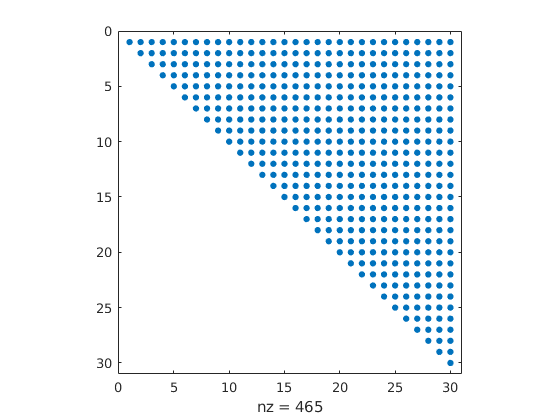

spy(R)

To learn about this function, see

help spy

 spy Visualize sparsity pattern.
    spy(S) plots the sparsity pattern of the matrix S.
 
    spy(S,'LineSpec') uses the color and marker from the line
    specification string 'LineSpec' (See PLOT for possibilities).
 
    spy(S,markersize) uses the specified marker size instead of
    a size which depends upon the figure size and the matrix order.
 
    spy(S,'LineSpec',markersize) sets both.
 
    spy(S,markersize,'LineSpec') also works.

    Documentation for spy



## Problem 3 (Orthogonal Polynomials)

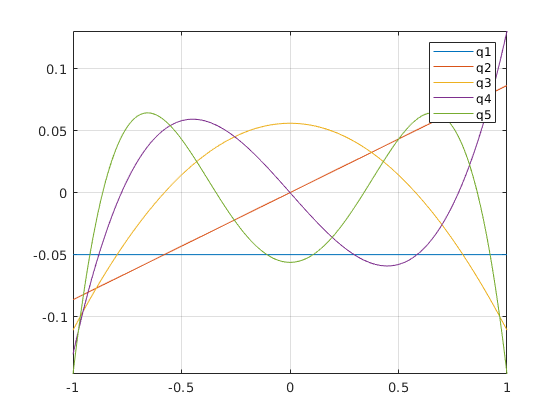

m = 400; n = 5;
x = linspace(-1, 1, m)';
V = x.^(0:n-1);
[Q,R] = qr(V,0);   % thin QR factorization

clf
plot(x, Q)
axis tight, grid on
legend('q1', 'q2', 'q3', 'q4', 'q5')

**Note 1.** The `plot` function smartly plots all columns of `Q` as functions of the common `x` when called with `plot(x, Q)`. This is the same as

Where does one learn about such tricks? Please read the very first paragraph of the help document for `plot`:

help plot

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

## Problem 4 (Visualizing Matrix Norms)

See the function `visMatrixNorms` at the end of this document.

A = [2 1;
     1 3];

$p = 1$:

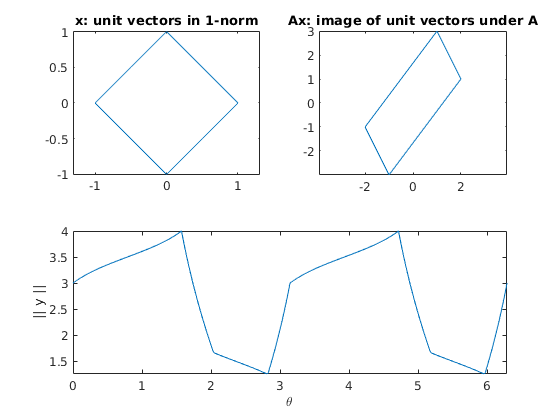

 p = 1
 approx. norm: 4.0000000000000000
 actual  norm: 4.0000000000000000


visMatrixNorms(A, 1);

$p = 2$:

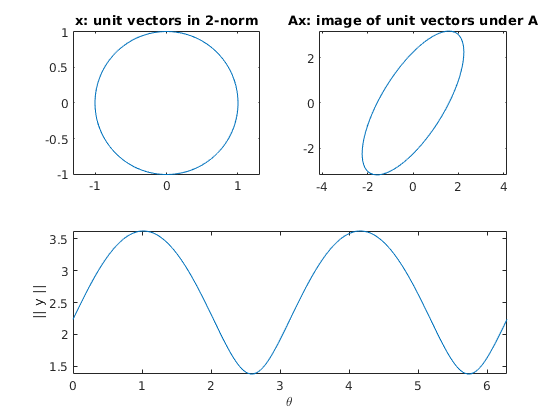

 p = 2
 approx. norm: 3.6179964204609893
 actual  norm: 3.6180339887498953


visMatrixNorms(A, 2);

$p=\infty$:

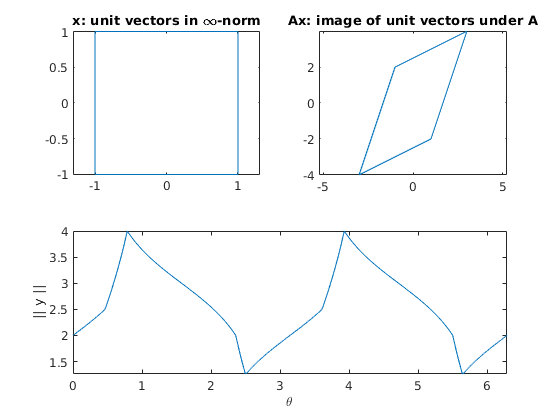

 p = Inf
 approx. norm: 3.9999999999999996
 actual  norm: 4.0000000000000000


visMatrixNorms(A, Inf);

### Explore.

Modify the script/function even further so that it can handle any $p \in [1, \infty]$. MATLAB's `norm` function can calculate vector $p$-norm for any value $p$, but it can only calculate $\Vert A \Vert_p$ for $p = 1, 2, \infty$ and $\Vert A \Vert_F$ (Frobenius norm). So for $p$ other than $1, 2, \infty$, your program must only output the approximate $\Vert A \Vert_p$. 

## Functions Used

### Gram-Schmidt

function [Q,R] = gs(A)
    n = size(A,2);
    Q = A;
    R = zeros(n);
    for j = 1:n
        if j > 1
            R(1:j-1,j) = Q(:,1:j-1)' * Q(:,j);
            Q(:,j) = Q(:,j) - Q(:,1:j-1)*R(1:j-1,j);
        end
        R(j,j) = norm(Q(:,j));
        Q(:,j) = Q(:,j)/R(j,j);
    end
end

### Visualization of Matrix Norms

function normA = visMatrixNorms(A, p)
% VISMATRIXNORM visMatrixNorms(A, p)
% Generate plots of unit vectors (in p-norm) and their images under A.
% Also approximates the matrix p-norm of A according to the definition of
% induced norms.
%
% Input:
%   A      2-by-2 matrix
%   p      1, 2, or Inf
% Output:
%  normA   matrix p-norm of A (approximation)
    if size(A,1)~=2 || size(A,2)~=2
        error('A must be a 2-by-2 matrix.')
    elseif p~=1 && p~=2 && p~=Inf
        error('p must be either 1, 2, or Inf.')
    end
    
    
    theta = linspace(0, 2*pi, 361);
    U = [cos(theta); sin(theta)];   % unit circle
    
    % Calculate p-norm of vectors on the unit circle
    if p == 1
        norm_U = sum( abs(U), 1 ); 
    elseif p == 2
        norm_U = sqrt( sum(abs(U).^2, 1) ); 
    else 
        norm_U = max( abs(U), [], 1 );
    end
    
    % Normalize to unit vectors in respective norm
    X = U ./ norm_U;
    
    % Calculate y's
    Y = A*X;
    
    % Calculate p-norm of y's
    if p == 1
        norm_Y = sum( abs(Y), 1 );
    elseif p == 2
        norm_Y = sqrt( sum(abs(Y).^2, 1) );
    else
        norm_Y = max( abs(Y), [], 1 );
    end
    normA = max(norm_Y);
    
    % Plotting routine
    clf
    subplot(2,2,1)
    plot(X(1,:), X(2,:)), axis equal
    
    if p ~= Inf
        str = sprintf('x: unit vectors in %g-norm', p);
    else
        str = sprintf('x: unit vectors in \\infty-norm', 'Interpreter', 'latex');
    end
    title(str)
    
    subplot(2,2,2)
    plot(Y(1,:), Y(2,:)), axis equal
    title('Ax: image of unit vectors under A')
    
    subplot(2,1,2)
    plot(theta, norm_Y), axis tight
    xlabel('\theta')
    ylabel('|| y ||')

    fprintf(' p = %g\n', p)
    fprintf(' approx. norm: %18.16f\n', normA)
    fprintf(' actual  norm: %18.16f\n', norm(A, p))
end